### Single Particle Model with Thermal (SPMT) using Orthogonal Chebyshev Collocation Method

clear;
clc;
addpath(genpath('dmsuite'));
addpath(genpath('model_parameters'));

% get lithium ion cell data
data = get_modelDataLGM50;

% Generate collocation nodes
N = 6; % N+1 is chebyshev nodes used to discretize solid diffusion equation
M = 2*N; % for discretizing 
nodes.xm = cos(pi*(0:M)/M)'; % [-R,R] -> [-1,1]
nodes.xr = nodes.xm(1:N+1); % [0,R] -> [0,1]

% Generate A,B,C,D state matrices for du/dt and concentration calculation
% Step 1: Create Differentiation matrix for second order
[~, D] = chebdif(M+1,2); % Create differentiation matrix for 1st and 2nd order
D1 = squeeze(D(1,:,1)); % [1,M+1] Access only first order differentiation matrix where r=1
D2 = squeeze(D(1:N,:,2)); % [N,M+1] Access 2nd order differentiation matrix for r=[1, 0]

% Step 2: Create Dn_delta matrix for convenience
P = fliplr(eye(N)); % Backward identity matrix
DN2 = D2(:,1:N) - D2(:,N+2:M+1)*P; % for 2nd order
DN1 = D1(1,1:N) - D1(1,N+2:M+1)*P; % for 1st order

% Step 3: Create A, B, C, D matrix for du/dt solid diffusion eqn
A = DN2(2:N,2:N) + (DN2(2:N,1)*DN1(1,2:N))/(1-DN1(1,1));
B = DN2(2:N,1)/(1-DN1(1,1));
C = DN1(1,2:N)/(1-DN1(1,1));
D = 1/(1-DN1(1,1));

% Step 4: Create An, Bn, Cn, Dn & Ap, Bp, Cp, Dp for each electrode particle using general A, B,
% C, D matrix
% Create for anode 
spm_matrices.An = (1/data.Rs1^2)*A;
spm_matrices.Bn = B;
spm_matrices.Cn = vertcat(C/data.Rs1, diag(1./(nodes.xr(2:N).*data.Rs1)));
spm_matrices.Dn = vertcat(data.Rs1*D, zeros(N-1,1));

% Create for cathode
spm_matrices.Ap = (1/data.Rs3^2)*A;
spm_matrices.Bp = B;
spm_matrices.Cp = vertcat(C/data.Rs3, diag(1./(nodes.xr(2:N).*data.Rs3)));
spm_matrices.Dp = vertcat(data.Rs3*D, zeros(N-1,1));

% Calculate Clenshaw-Curtis quadrature weights for calculating integrals
[~,wm] = clencurt(M);
wn = horzcat((wm(1:N) + wm(N+2:M+1)*P), wm(N+1));
spm_matrices.wn = wn;

% Set initial condition for the model
x1_init = data.x1_soc1; % Setting anode 100% SOC (stoichiometry @ 100% SOC)
y3_init = data.y3_soc1; % Setting cathode 0% SOC (stoichiometry @ 0% SOC)
T_init = data.T_amb; % Reference ambient temperature

% Set initial surface concentration and its U surface (u = r*cs)
% Stoichiometry = Cs/Cs_max

initSPM.cs1 = data.cs1_max*x1_init; % Anode surface concentration
initSPM.cs3 = data.cs3_max*y3_init; % Cathode surface concentration
initSPM.us1 = initSPM.cs1.*nodes.xr(2:N).*data.Rs1;
initSPM.us3 = initSPM.cs3.*nodes.xr(2:N).*data.Rs3;
initSPM.T = T_init;

% Set initial state vector for ODE solving
initSPM.x0 = [initSPM.us3; initSPM.us1; initSPM.T];

% Define voltage limit, current and time vector
vLim = [2.5, 4.2];
tspan = 0:1:3600;
crate = 1;
I = @(t) crate*data.C_nom.*ones(size(t));


event = @(t,u) cutOffVoltage(t, u, I, data, spm_matrices, N, vLim);
fun = @(t,u) calculate_dudt(t, u, I, data, spm_matrices, N);
opt = odeset('Events',event);
[result.time, result.state] = ode45(fun, tspan, initSPM.x0, opt);

voltage = zeros(length(result.time),1);
temperature = zeros(length(result.time),1);

for i=1:length(result.time)
    t = result.time(i);
    state = real(result.state(i,:)');
    [voltage(i), temperature(i)] = calculate_volt_temp(t, state, I, data, spm_matrices, N); 
end

[cs1, cs3, cs1avg, cs3avg] = calculate_concentration(result.time', real(result.state'), I, data, spm_matrices, N, nodes);

SOC1 = 100*(cs1avg/data.cs1_max - data.x1_soc0)/(data.x1_soc1 - data.x1_soc0);
SOC3 = 100*(cs3avg/data.cs3_max - data.y3_soc0)/(data.y3_soc1 - data.y3_soc0);

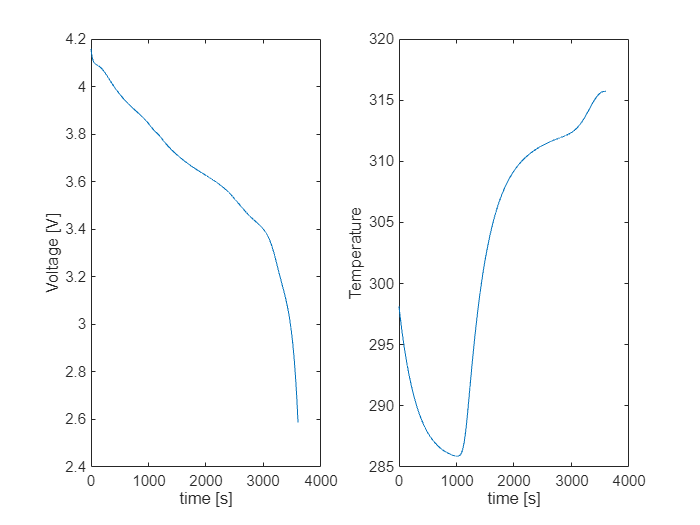

figure(1)
subplot(1,2,1)
plot(result.time, voltage)
xlabel('time [s]'); ylabel('Voltage [V]')

subplot(1,2,2)
plot(result.time, temperature)
xlabel('time [s]'); ylabel('Temperature')